# File Name: MATLAB_Basic_03_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Read a point cloud.

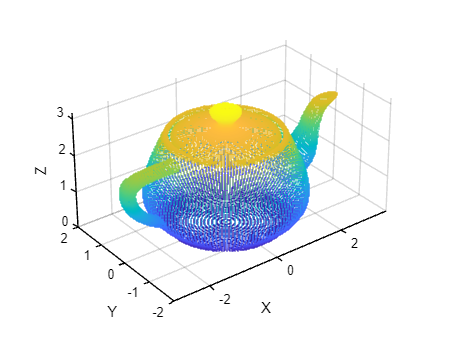

InputPointCloud = pcread('teapot.ply');

%%%%%%%%%% TODO %%%%%%%%%%
% Visualize point cloud.
pcshow(InputPointCloud);

xlabel('X');
ylabel('Y');
zlabel('Z');
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], 'YColor', [0. 0. 0.], 'ZColor', [0. 0. 0.])

## Random sample downsample method

Set the random sampling percentage.

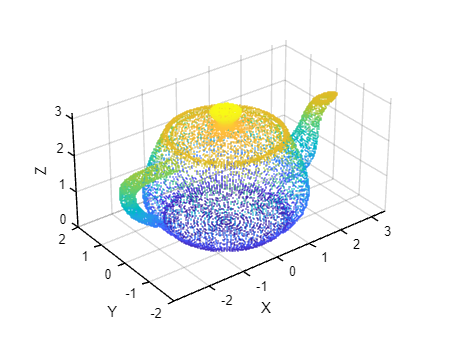

percentage = 0.4;

%%%%%%%%%% TODO %%%%%%%%%%
% Downsample point cloud using random sample method.
randomDownsampledPointCloud = pcdownsample(InputPointCloud,"random",percentage);

% Visualize the downsampled data.
figure;
pcshow(randomDownsampledPointCloud);
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], 'YColor', [0. 0. 0.], 'ZColor', [0. 0. 0.])

## Gridsample downsample method

Set the 3-D resolution to be (0.1 x 0.1 x 0.1).

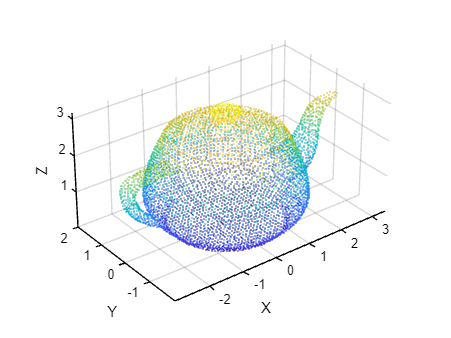

gridStep = 0.1;

%%%%%%%%%% TODO %%%%%%%%%%
% Downsample point cloud using grid average method.
GridAverageDownsampledPointCloud = pcdownsample(InputPointCloud,"gridAverage", gridStep);

% Visualize the downsampled data.
figure();
pcshow(GridAverageDownsampledPointCloud);
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], 'YColor', [0. 0. 0.], 'ZColor', [0. 0. 0.])